# Trabajo práctico: Etapas típicas en procesamiento digital de señales

## Generación de una señal con cierta frecuencia de muestreo

1. Escriba un programa en MATLAB que grafique una función senoidal con las siguientes especificaciones:

- Frecuencia: 100 Hz.

- Frecuecia de muestreo: 1000 Hz.

- Tiempo inicio: 0 s.

- Tiempo final: 1 s.

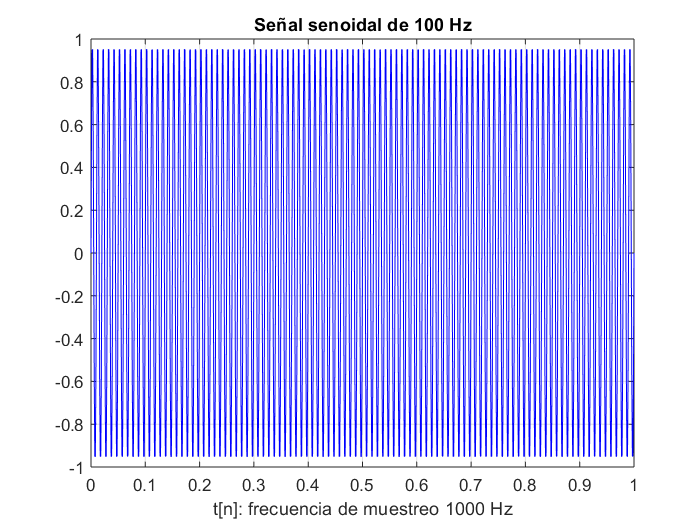

fN = 100; fS = 1000; t0 = 0; tF = 1;

TS = 1 / fS;
t = t0:TS:tF;

signal = sin(2*pi*fN*t);

figure(1)
plot(t, signal, '-b');
grid on;
title("Señal senoidal de 100 Hz");
xlabel("t[n]: frecuencia de muestreo 1000 Hz");

## Agregar ruido a una señal

2. Escriba un programa en MATLAB que permita agregar a la señal del Ejercicio 1 cierta cantidad de ruido blanco gaussiano.

    1. Obtenga la varianza del ruido a partir de la relación:


$$SNR = 10 \log \frac{\sigma^{2}_{signal}}{\sigma^{2}_{noise}}$$


    2. Utilice la función `randn() `para simular el ruido (`help randn`).

    3. El prototipo de la función debe ser `signal_n = my_awgn(signal, snr)`. Los datos de entrada son el vector `signal` y el escalar `snr`.

    4. La varianza de signal se puede calcular con la función `var` (`help var`).

    5. Compare las salidas de las funciones `my_awgn` y `awgn` (`help awgn`).

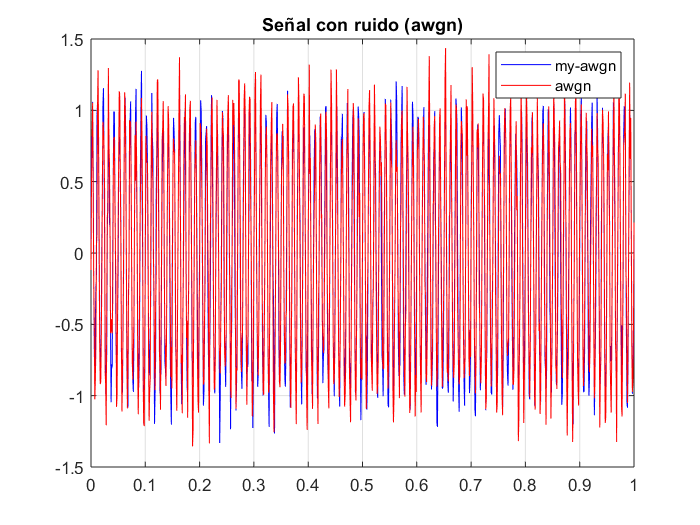

figure(2)
plot(t, my_awgn(signal, 15), '-b');
title("Señal con ruido (awgn)");
hold on;
plot(t, awgn(signal, 15), '-r');
grid on;
legend("my-awgn", "awgn");

## Efecto aliasing

3. Ejecute el modelo de Simulink provisto, `aliasing_demo.mdl`. En este modelo se genera una señal de 100 Hz muestreada a 10 kHz. El bloque ZOH la vuelve a muestrear. Finalmente se grafica su respuesta en frecuencia con un analizador de espectro.

    1.  Observe la pantalla del analizador de espectro. ¿Qué se debería ver?

En el analizador de espectro se debería observar un pico en 100 Hz, que es la frecuencia de la señal. Sin embargo, se observa un **pico en 50 Hz**.

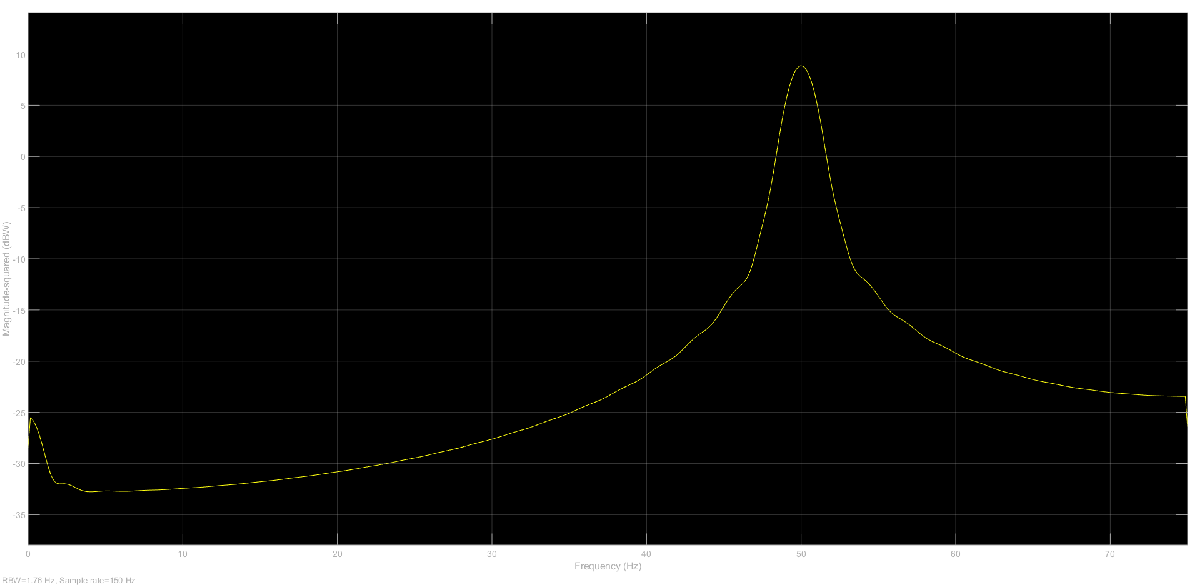

Además, también se observa un **valor en continua** (frecuencia 0), cuando al ser una señal senoidal este valor debería ser nulo.

    2. ¿A qué frecuencia está trabajando el bloque ZOH?

El bloque ZOH se encuentra trabajando a **150 Hz**.

    3. ¿Qué debe modificar en el modelo para evitar el efecto de aliasing?

Hay **aliasing** debido a que la frecuencia de muestreo, es decir, frecuencia a la que trabaja el bloque ZOH, debe ser al menos 2 veces la máxima frecuencia de la señal (en este caso esa frecuencia es única).

A continuación, el analizador de espectro para una frecuencia de funcionamiento del bloque ZOH de **200 Hz**:

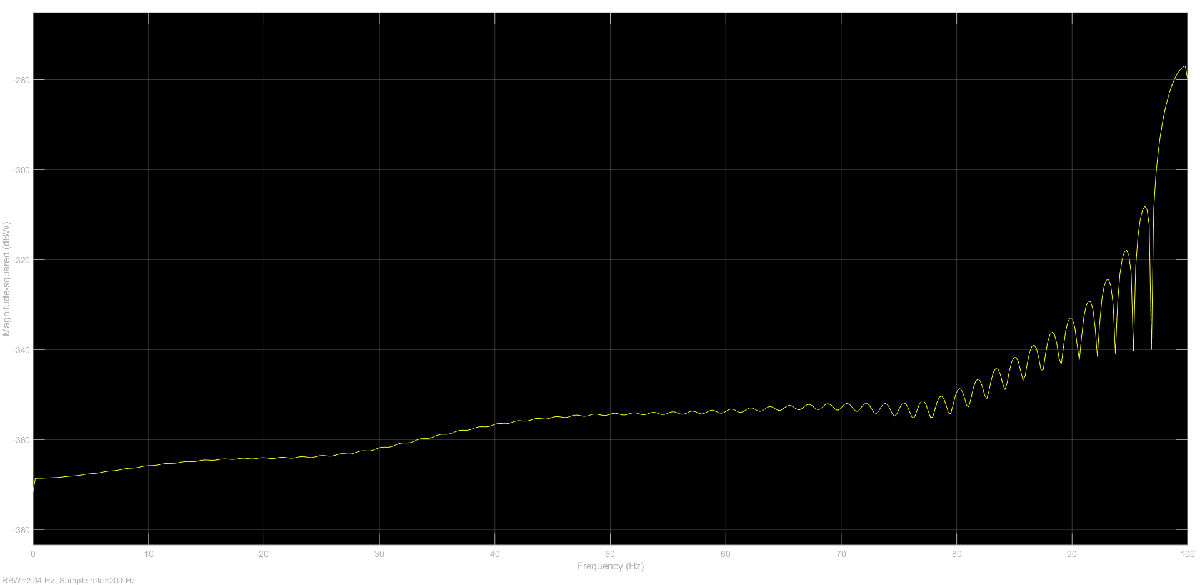

En este caso se puede observar un pico en 100 Hz, sin embargo, como también coincide con la máxima frecuencia que se puede observar, se puede mejorar aún más aumentando la frecuencia de funcionamiento del bloque ZOH, por ejemplo,  a 500 Hz.

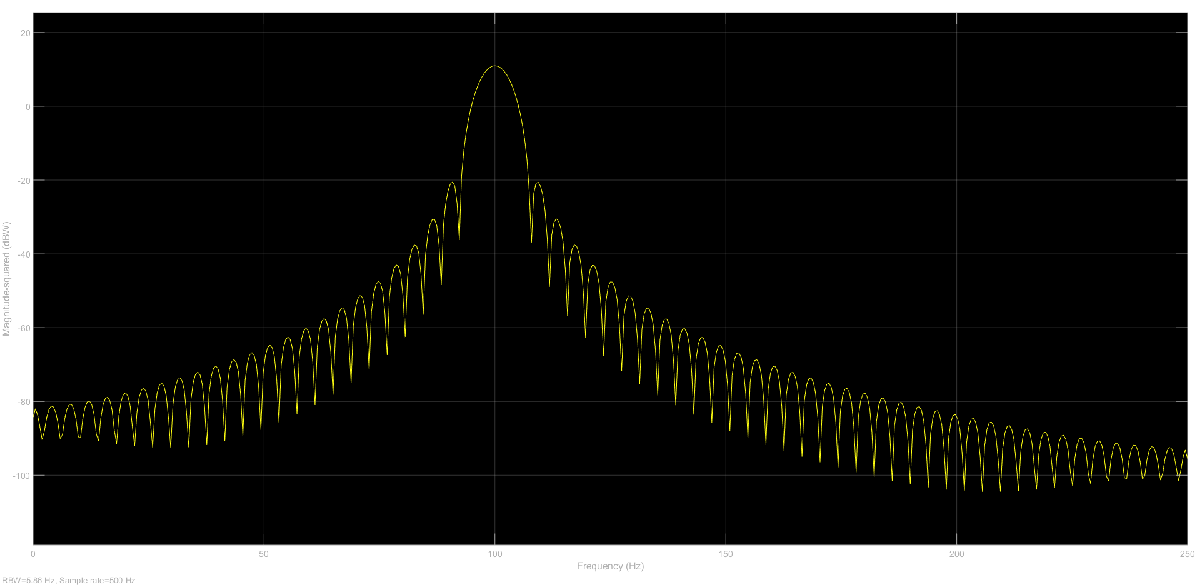

En este último caso incluso puede observarse como los **glóbulos laterales del espectro están por debajo de -20 dB**.

## Acondicionamiento de señal y error de cuantización

4. Ejecute el modelo de Simulink provisto, `adc_demo.mdl`. El objetivo del ejercicio es representar la señal de entrada aguas abajo del ADC con los mismos valores de la señal original.

load('adc_acond.mat');

    1. ¿Observa algún error en la salida del ADC? ¿Cómo solucionaría el problema?

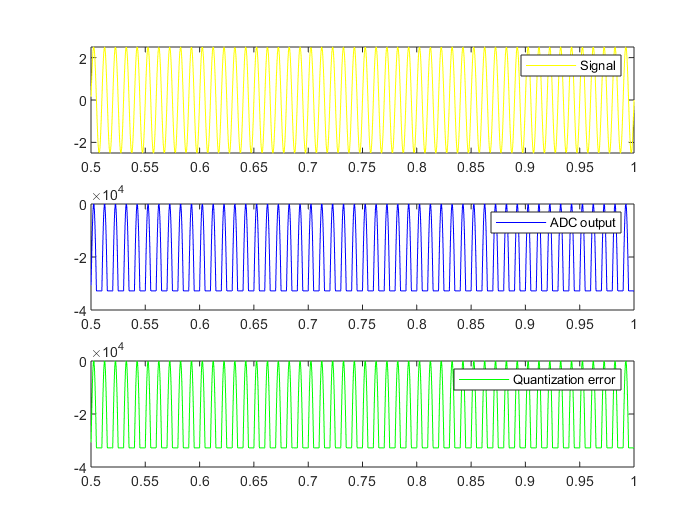

figure(3)
subplot(3, 1, 1);
plot(ADC_raw.time, ADC_raw.signals(1).values, '-y');
legend("Signal");
subplot(3, 1, 2);
plot(ADC_raw.time, ADC_raw.signals(2).values, '-b');
legend("ADC output");
subplot(3, 1, 3);
plot(ADC_raw.time, ADC_raw.signals(3).values, '-g');
legend("Quantization error");

Este error es debido a que la señal varía entre -2.5 V a +2.5 V, mientras que el ADC opera entre 0 y +5 V. Una forma de solucionar esto es dando un offset o bias de 2.5V en la señal (corrimiento del 0).

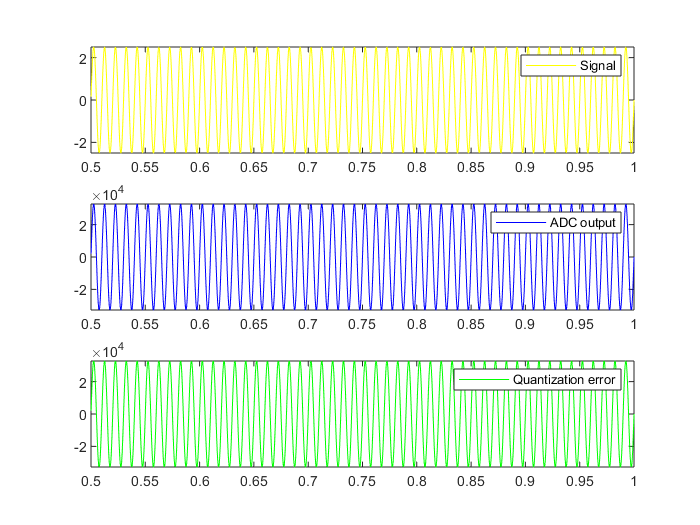

figure(4)
subplot(3, 1, 1);
plot(ADC_bias.time, ADC_bias.signals(1).values, '-y');
legend("Signal");
subplot(3, 1, 2);
plot(ADC_bias.time, ADC_bias.signals(2).values, '-b');
legend("ADC output");
subplot(3, 1, 3);
plot(ADC_bias.time, ADC_bias.signals(3).values, '-g');
legend("Quantization error");

    2. Analice el error de cuantización. ¿Es correcto su valor? De no ser así, ¿qué solución propone?

El error de cuantización sigue siendo incorrecto, esto se debe a que todavía no se escala la salida de la conversión, tarea que realizaría el *Coder*, dandole significado a la representación en bits. Esto se logra multiplicando la salida por una ganancia igual a la presición de la conversión *q*, es decir:


$$q = \frac{2V_{P}}{2^{B}} = 7.629 \times 10^{-5}$$


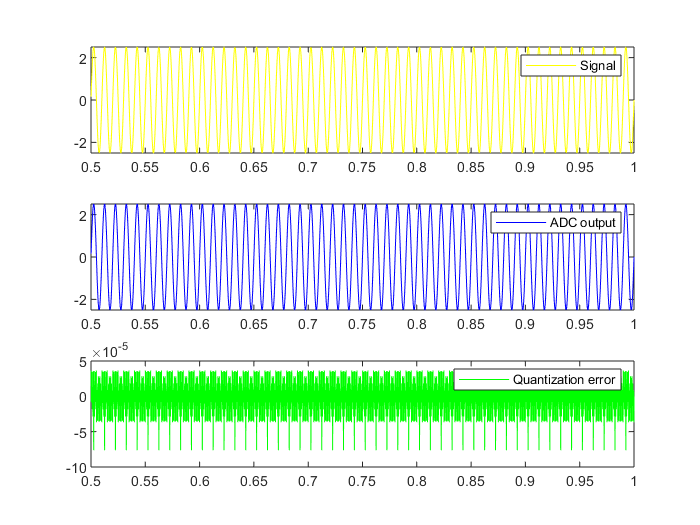

figure(5)
subplot(3, 1, 1);
plot(ADC_ans.time, ADC_ans.signals(1).values, '-y');
legend("Signal");
subplot(3, 1, 2);
plot(ADC_ans.time, ADC_ans.signals(2).values, '-b');
legend("ADC output");
subplot(3, 1, 3);
plot(ADC_ans.time, ADC_ans.signals(3).values, '-g');
legend("Quantization error");

    3. ¿Qué propone para disminuir este error?

La expresión del $SNR_{ADC}$ para una señal sinusoidal es como sigue:

$SNR_{ADC} = 20\cdot \log_{10}\left(\frac{1}{\sqrt{2}}\right) + 4.77 + 6.02 \cdot B$   [dB]

Por lo tanto solo se puede aumentar la relación señal ruido **aumentando la cantidad de bits del conversor analógico digital**.

    4. Agregue un display que muestre la ecuación de la teoría $SNR_{ADC}$ y compare su resultado para diferentes cantidad de bits del ADC.

B = 16;
SNR = 20*log(1/sqrt(2)) + 4.77 + 6.02*B;
disp("B = " + B + "    SNR = " + SNR);

B = 16    SNR = 94.1585


## Error de cuantización, aspectos teóricos

5. Suponga que tenemos un ADC de 12 bits que opera sobre un rango de $\pm5 V$. Asuma que el ADC es ideal y que su función de transferencia está dada por la siguiente figura,

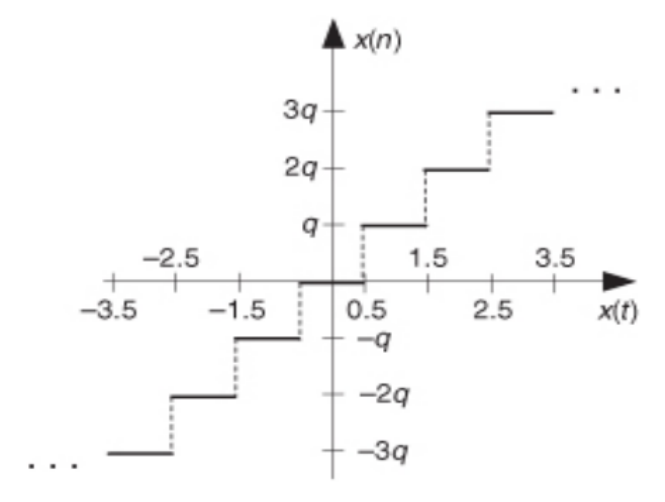

a) ¿Cuál es el nivel de cuantización *q* del ADC, dada en voltios?

El nivel de cuantización está dado por $q = \frac{2V_{P}}{2^{B}}$, por lo tanto para $\pm5 V$ y 12 bits, será aproximadamente de **2.44 mV**.

b) Si se aplica una señal sinusoidal de 7 V pico a pico, ¿qué nivel de $SNR_{ADC}$ se puede esperar? Desarrolle la respuesta.

El nivel de $SNR_{ADC}$ esta dado por la siguiente expresión:

$SNR_{ADC} = 20\cdot \log_{10}\left(\frac{rms_{signal}}{V_{P}}\right) + 4.77 + 6.02 \cdot B$   [dB]

Para una señal sinusoidal, $rms_{signal} = V_{P} / \sqrt{2}$, por lo tanto $SNR_{ADC} = 74$ dB. Dado que hay factores que se pudo no tener en cuenta, este valor puede decrementarse 3 o 6 dB.

SNR = 20*log(1/sqrt(2)) + 4.77 + 6.02*B  - 3;
disp("SNR = " + SNR);

SNR = 91.1585
